# Summary Results Demo

Use SummaryResults function to compare the costs values for the diferent states of the plant

#### Select and check the model file

filename="D:\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(filename);

#### Select the parameters

param=struct();
if data.isResourceCost
    Samples=convertCharsToStrings(data.getSampleNames);
    param.ResourceSample=convertStringsToChars(Samples(1));
end

#### Obtain the Summary Results

res=SummaryResults(data,param);
printResults(res);

Summary Flows Exergy (kW)

 Key           REF    ETAT75    ETAC75    TCND35    TBLR85      W200
—————————————————————————————————————————————————————————————————————
 B1          620.8     637.8     620.8     694.0     641.4    1172.0
 B2          317.8     326.9     317.8     390.3     339.5     599.8
 B3          281.6     289.3     281.6     317.4     301.5     531.5
 B4          294.3     302.3     294.3     331.1     313.3     555.4
 B5          220.7     220.7     215.2     197.9     220.7     220.7
 B6          194.0     194.0     189.2     167.1     194.0     194.0
 B7           59.6      59.6      58.1      53.0      59.6      59.6
 B8          244.5     244.5     238.5     238.6     244.5     244.5
 WT          245.1     245.5     245.1     246.3     244.2     462.6
 WC          230.0     230.0     230.0     230.0     230.0     230.0
 WP           14.8      15.2      14.8      15.9      13.9      27.9
 QBLR        462.1     474.8     462.1     505.9     477.2     872.1
 QEVP 

#### Show the default summary results graph

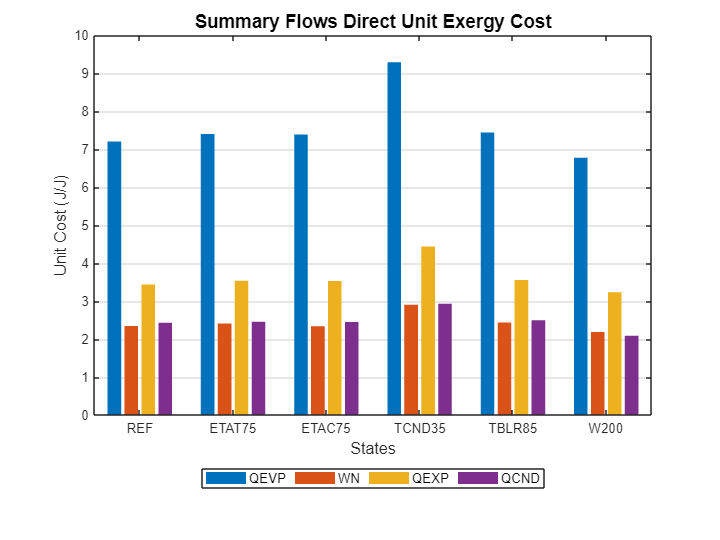

ShowGraph(res);

#### Save the summary results into an excel file

outfile='SummaryResults.xlsx';
SaveOption=true;
if SaveOption
    SaveResults(model,outfile);
end

INFO: cStatusLogger. File SummaryResults.xlsx has been saved


**Select Additional Tables for ShowResults/ShowGraph**

Show the index table for summary results

ShowResults(res,'Table',cType.TABLE_INDEX)

 Key      Description                                 Graph  
———————————————————————————————————————————————————————————————
 exergy   Summary Flows Exergy                        false  
 pku      Summary Process Unit Consumption            true   
 pI       Summary Process Irreversibility             false  
 dpc      Summary Processes Direct Exergy Cost        false  
 dpuc     Summary Processes Direct Unit Exergy Cost   true   
 dfc      Summary Flows Direct Exergy Cost            false  
 dfuc     Summary Flows Direct Unit Exergy Cost       true   
 gpc      Summary Processes Generalized Cost          false  
 gpuc     Summary Processes Generalized Unit Cost     true   
 gfc      Summary Flows Generalized Cost              false  
 gfuc     Summary Flows Generalized Unit Cost         true   



Select a table from the available tables.

tables=convertCharsToStrings(res.getListOfTables);
table=convertStringsToChars(tables(9));
tp=ShowResults(res,'Table',table);

Summary Processes Generalized Unit Cost (c/kWh)

 Key           REF    ETAT75    ETAC75    TCND35    TBLR85      W200
—————————————————————————————————————————————————————————————————————
 BLR        0.7130    0.6938    0.7075    0.9655    0.7358    0.4101
 TRB        2.2357    2.2470    2.2269    2.6329    2.2510    1.0764
 PMP        8.4253    8.3141    8.4123    8.6341    8.9058    1.9401
 CMP        4.3271    4.3365    4.4363    5.1355    4.3383    2.5721
 EVAP       9.7385    9.7583    9.9875   11.5501    9.7621    6.0637
 GEN        6.6863    6.5801    6.6771    6.8082    7.0120    1.3846
 VEXP       4.3732    4.3827    4.4837    5.1756    4.3845    2.6182
 CND        3.5328    3.4636    3.5612    3.2765    3.4753    1.7990



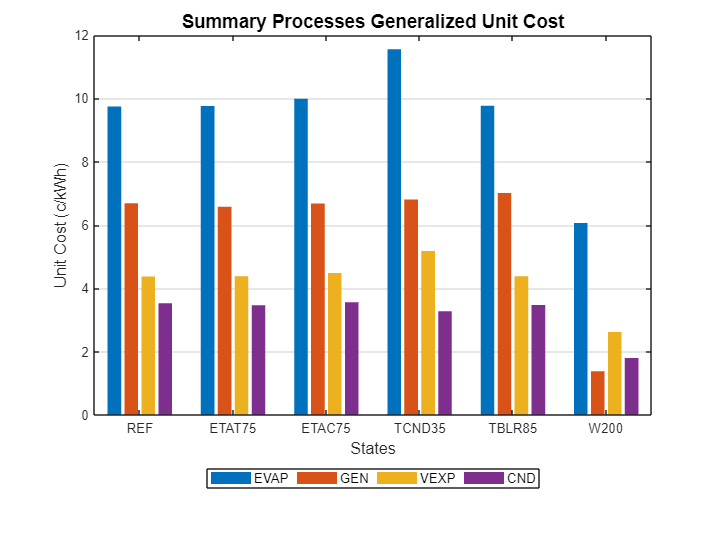

if isGraph(tp)
    ShowGraph(res,'Graph',table);
end